# Regression Prediction Of House Price

Kevin Chng, AE, TechSource

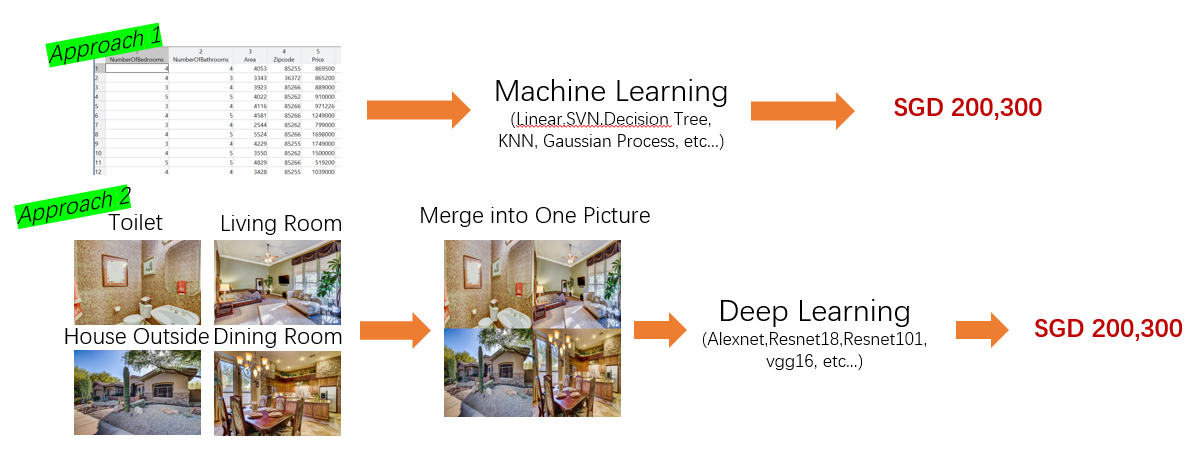

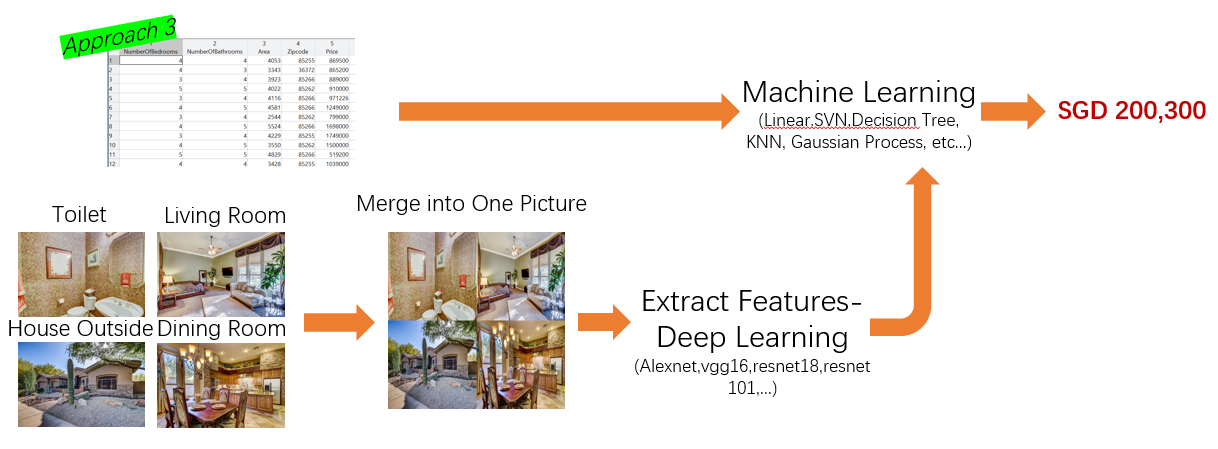

clear all
clc

%Assign same randoness
rng(10)

## Activate Parallel Computing Toolbox

if isempty(gcp('nocreate'))
parpool;
end

Starting parallel pool (parpool) using the 'local' profile ...


## Approach 1 Machine Learning

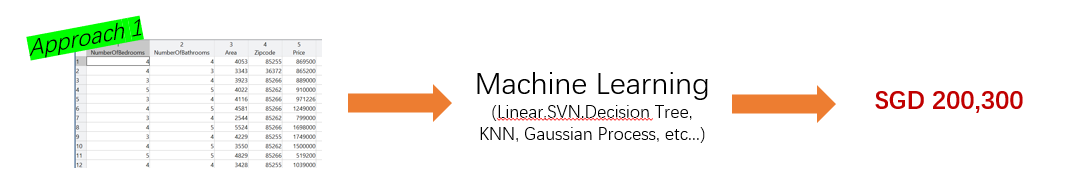

Data = importfile("Houses-dataset-master\Houses Dataset\HousesInfo.txt");
parfor i=1:1:height(Data)
ImageName(i)=sprintf("Dataset%4i.png",i);
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


%Add ImageName to the Data, so it can represent the data
Data.ImageName = ImageName';

%Change the datatype
Data.Price=double(Data.Price);
Data.Zipcode = categorical(Data.Zipcode);

%Change the datatype of Price from String to Double
head(Data)

ans = 8×6 table
    NumberOfBedrooms    NumberOfBathrooms    Area    Zipcode      Price           ImageName    
    ________________    _________________    ____    _______    __________    _________________
           4                    4            4053     85255      8.695e+05    "Dataset   1.png"
           4                    3            3343     36372      8.652e+05    "Dataset   2.png"
           3                    4            3923     85266       8.89e+05    "Dataset   3.png"
           5                    5            4022     85262        9.1e+05    "Dataset   4.png"
           3                    4            4116     85266     9.7123e+05    "Dataset   5.png"
           4                    5            4581     85266      1.249e+06    "Dataset   6.png"
           3

Partition the train data and test data

c = cvpartition(Data.Price,'holdout',0.3)

c = Hold-out cross validation partition
   NumObservations: 535
       NumTestSets: 1
         TrainSize: 375
          TestSize: 160

Training_Data_1 = Data(c.training,:);
Testing_Data_1 = Data(c.test,:);

Open classification learner apps to train the data, remember to untick ImageName as it is not a predictor. Price is the result, it should not be our pretictor as well

regressionLearner;

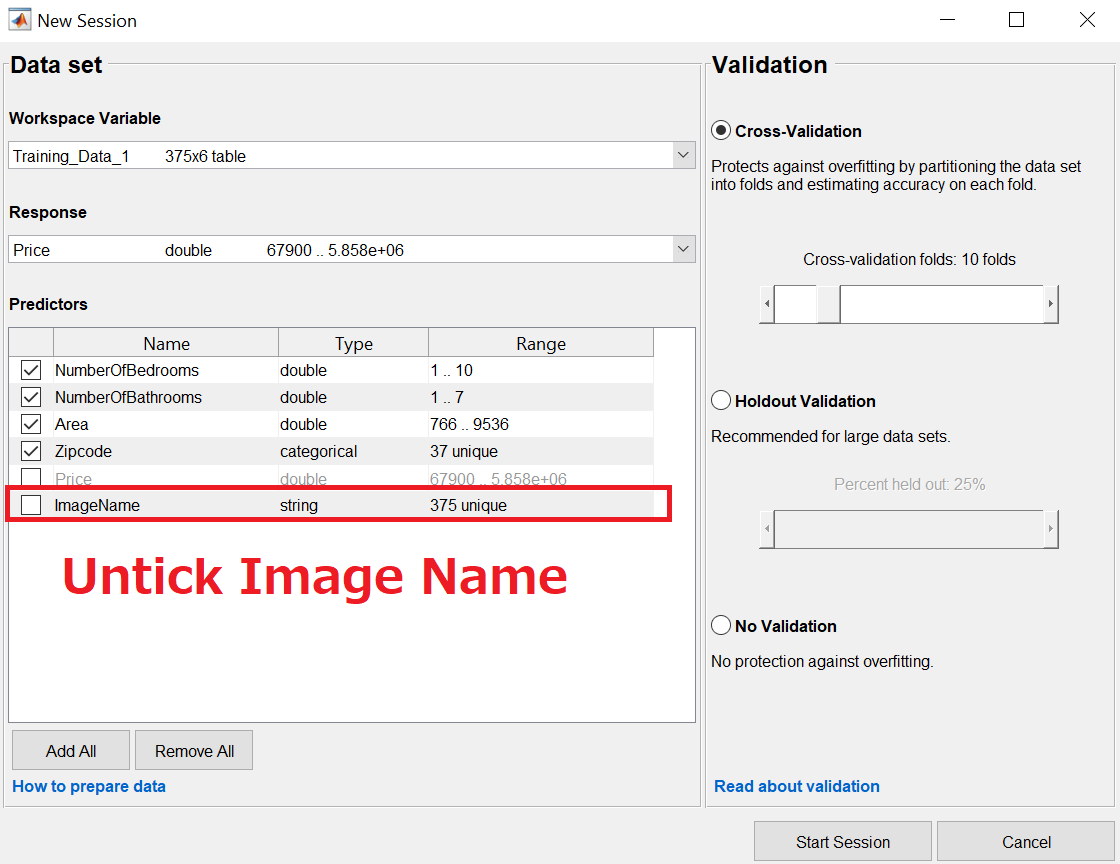

After training, you may export the best model. I have trained the model, you may load the model and justify the accuracy. 

I have save the model in classificationmachinelearning.mat

load regressionmachinelearning.mat
regressionmachinelearning

regressionmachinelearning = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Area'  'NumberOfBathrooms'  'NumberOfBedrooms'  'Zipcode'}
        RegressionSVM: [1×1 RegressionSVM]
                About: 'This struct is a trained model exported from Regression Learner R2019a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'

## Justify the accuracy with testing dataset (Mean Square Error)

YPred = regressionmachinelearning.predictFcn(Testing_Data_1);
table_MAE = table(Testing_Data_1.Price,YPred);
table_MAE = rmmissing(table_MAE);
table_MAE.Properties.VariableNames(1)="Price";
table_MAE.Properties.VariableNames(2)="YPred";
MAE = abs(sum(table_MAE.Price-table_MAE.YPred)/numel(table_MAE.Price))

MAE = 8.3585e+04

Price = cur2str(Testing_Data_1.Price,2);
YPred = cur2str(YPred,2);
result=table(Testing_Data_1.ImageName,Price,YPred);
result.Properties.VariableNames(1)="Name";
result.Properties.VariableNames(2)="Actual_Price";
result.Properties.VariableNames(3)="Predicted_Price"

result = 160×3 table
          Name           Actual_Price    Predicted_Price
    _________________    ____________    _______________
    "Dataset  33.png"     $365000.00       [1x11 char]  
    "Dataset  45.png"     $350000.00       [1x11 char]  
    "Dataset  51.png"     $214900.00       [1x11 char]  
    "Dataset  60.png"     $104900.00       [1x11 char]  
    "Dataset  61.png"     $209900.00       [1x11 char]  
    "Dataset  63.png"     $249900.00       [1x11 char]  
    "Dataset  64.png"     $119000.00       [1x11 char]  
    "Dataset  65.png"     $218000.00       [1x11 char]  
    "Dataset  66.png"     $254900.00       [1x11 char]  
    "Dataset  67.png"     $219500.00       [1x11 char]  
    "Dataset  68.png"     $186500.00       [1x11 char]  
    "Dataset  69.png"     $94500.00        [1x11 char]  
    "Dataset  70.png"     $339900.00       [1x11 char]  
    "Dataset  71.png" 

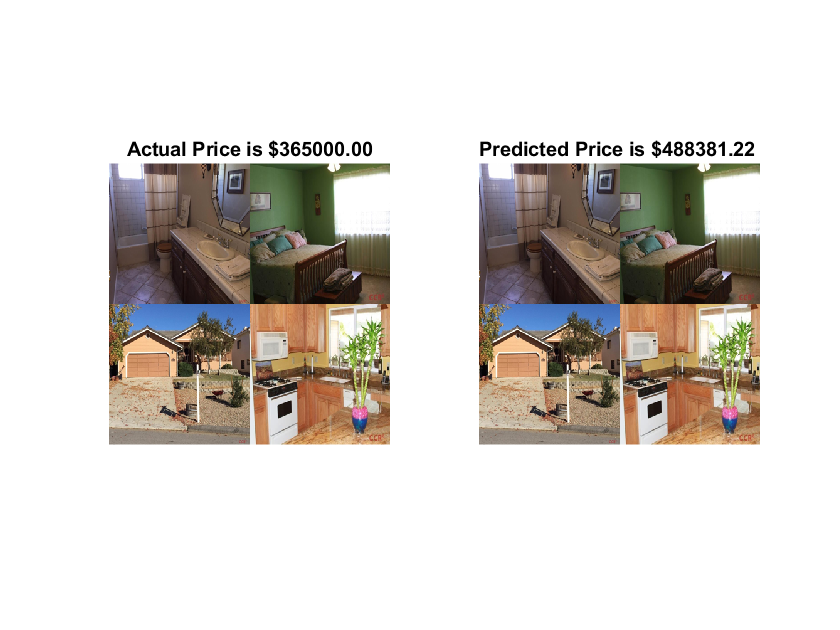

subplot(1,2,1)
imshow(strcat("NewImage\",result.Name(1)))
title(sprintf("Actual Price is %s",result.Actual_Price(1,:)))
subplot(1,2,2)
imshow(strcat("NewImage\",result.Name(1)))
title(sprintf("Predicted Price is %s",result.Predicted_Price(1,:)))

Here, you can apply some pre-processing technique to improve the accuracy, for example, remove outliers.

## Approach 2 Deep Learning

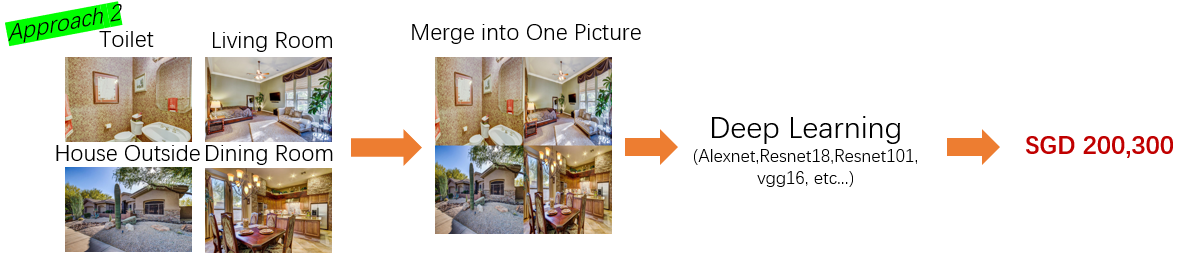

Create the Image Datastore with Label, Split the Data to Train Data and Validation Data

imds = imageDatastore("NewImage","Labels",Data.Price);
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

### Reconstructure the datastore into 4D-array

clearvars imdsTrain_nn imdsValidation_nn

imdsTrain_n=readall(imdsTrain);
for i=1:1:length(imdsTrain_n)
    imdsTrain_nn(:,:,:,i) =  imresize(imdsTrain_n{i},[227 227]);    
end
imdsValidation_n=readall(imdsValidation);
for i=1:1:length(imdsValidation_n)
    imdsValidation_nn(:,:,:,i) =  imresize(imdsValidation_n{i},[227 227]);    
end

### Load the Network

Create your network

layers = [
    imageInputLayer([227 227 3],"Name","data")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(1,"Name","fc")
    regressionLayer("Name","regressionoutput")];

### Specify the training options

You might lower down the MiniBatchSize and MaxEpochs to accelerate the training and better handle of the memory.

miniBatchSize  = 10;
validationFrequency = floor(numel(imdsTrain.Labels)/miniBatchSize);
options = trainingOptions('rmsprop', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',200, ...
    'InitialLearnRate',1e-3, ...
    'ValidationData',{imdsValidation_nn,imdsValidation.Labels}, ...
    'ValidationFrequency',3, ...
    'Plots','training-progress', ...
    'Verbose',false);

By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™ and a CUDA® enabled GPU with compute capability 3.0 or higher). Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

### Train the Deep Learning Networks 

reply = questdlg('Do you want train your deep learning network?It will spend few minutes. You may load the trained deep learning network','Deep Learning Classification','Train','Load','Load');
if strcmp(reply,'Train')==1
    netTransfer = trainNetwork(imdsTrain_nn,imdsTrain.Labels,layers,options);
else
    load regressiondeeplearning.mat
end

## Classify Validation Images & Calculate the Accuracy using Validation Image

Classify the validation images using the fine-tuned network.

YPred= predict(netTransfer,imdsValidation_nn);

table_MAE = table(imdsValidation.Labels,YPred);
table_MAE = rmmissing(table_MAE);
table_MAE.Properties.VariableNames(1)="Price";
table_MAE.Properties.VariableNames(2)="YPred";
MAE = abs(sum(table_MAE.Price-table_MAE.YPred)/numel(table_MAE.Price))

MAE = single
1.5746e+05

Price = cur2str(imdsValidation.Labels,2);
YPred = cur2str(YPred,2);
result=table(imdsValidation.Files,Price,YPred);
result.Properties.VariableNames(1)="Name";
result.Properties.VariableNames(2)="Actual_Price";
result.Properties.VariableNames(3)="Predicted_Price"

result = 111×3 table
                                                                       Name                                                                        Actual_Price    Predicted_Price
    ___________________________________________________________________________________________________________________________________________    ____________    _______________
    'C:\Users\KevinChng\Desktop\TechSource\Customer Visit\87 Krungsi Bank\1. Reply Email Material\Predict House Price\NewImage\Dataset  10.png'    [1x11 char]       $757246.44   
    'C:\Users\KevinChng\Desktop\TechSource\Customer Visit\87 Krungsi Bank\1. Reply Email Material\Predict House Price\NewImage\Dataset  12.png'    [1x11 char]       $516293.88   
    'C:\Users\KevinChng\Desktop\TechSource\Customer Visit\87 Krungsi Bank\1. Reply Email Material\Predict House Price\NewImage\Dataset  14.png'    [1x11 char]   

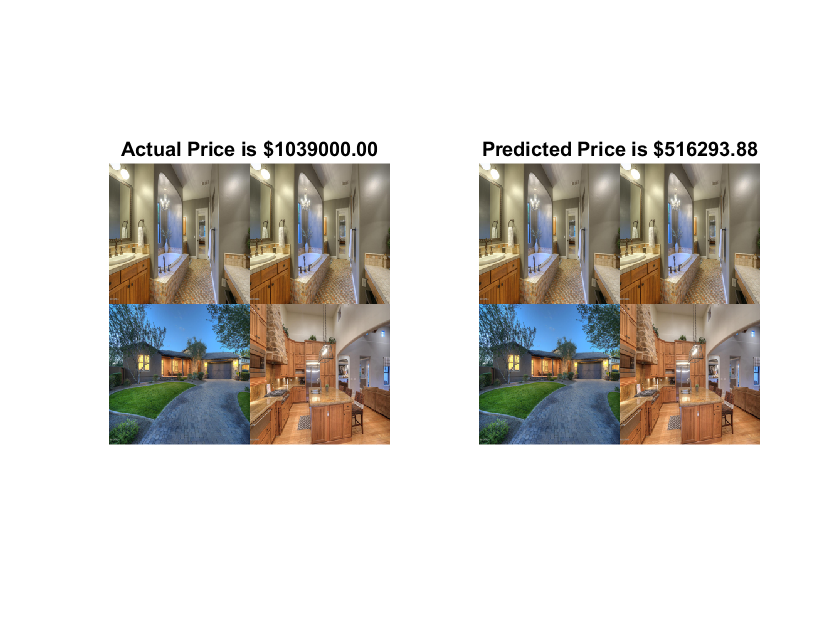

subplot(1,2,1)
imshow(imdsValidation.Files{2})
title(sprintf("Actual Price is %s",result.Actual_Price(2,:)))
subplot(1,2,2)
imshow(imdsValidation.Files{2})
title(sprintf("Predicted Price is %s",result.Predicted_Price(2,:)))

## Approach 3 Mahine Learning + Deep Learning

### Extract the Features from Deep Learning

follows classification method first to extract the feature, however,later use regression learner in machine learning part.

[The activation here does not support regression label for datastore-hopefully it can get update soon to support it]

Data = preprocessing;
imds = imageDatastore("NewImage","Labels",Data.Label);
[imdsTrain2,imdsValidation2] = splitEachLabel(imds,0.7,'randomized');
net = resnet18;
inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain2);
augimdsValidation = augmentedImageDatastore(inputSize,imdsValidation2);
layer = 'pool5';
featuresTrain = activations(net,augimdsTrain,layer,'OutputAs','rows');
featureValidation = activations(net,augimdsValidation,layer,'OutputAs','rows');

### Assign all  the predictors into table for Machine Learning

table_o= array2table([featuresTrain;featureValidation]);
table_o.FileNames = [augimdsTrain.Files(:);augimdsValidation.Files(:)];

table_o= sortrows(table_o,"FileNames");
table_o = [table_o Data(:,1:5)];

Visualize the table

table_o

table_o = 535×518 table
      Var1       Var2       Var3       Var4        Var5       Var6        Var7       Var8       Var9       Var10      Var11       Var12      Var13       Var14      Var15       Var16        Var17      Var18      Var19      Var20       Var21       Var22      Var23       Var24      Var25       Var26      Var27      Var28       Var29       Var30       Var31      Var32      Var33      Var34       

### Partition the train data and test data

c = cvpartition(table_o.Zipcode,'holdout',0.3)

c = Hold-out cross validation partition
   NumObservations: 535
       NumTestSets: 1
         TrainSize: 375
          TestSize: 160

Training_Data_2 = table_o(c.training,:);
Testing_Data_2 = table_o(c.test,:);

### Train Machine Learning Model

Open classification learner apps to train the data, remember to untick ImageName as it is not a predictor. Price is the result, it should not be our pretictor as well

regressionLearner;

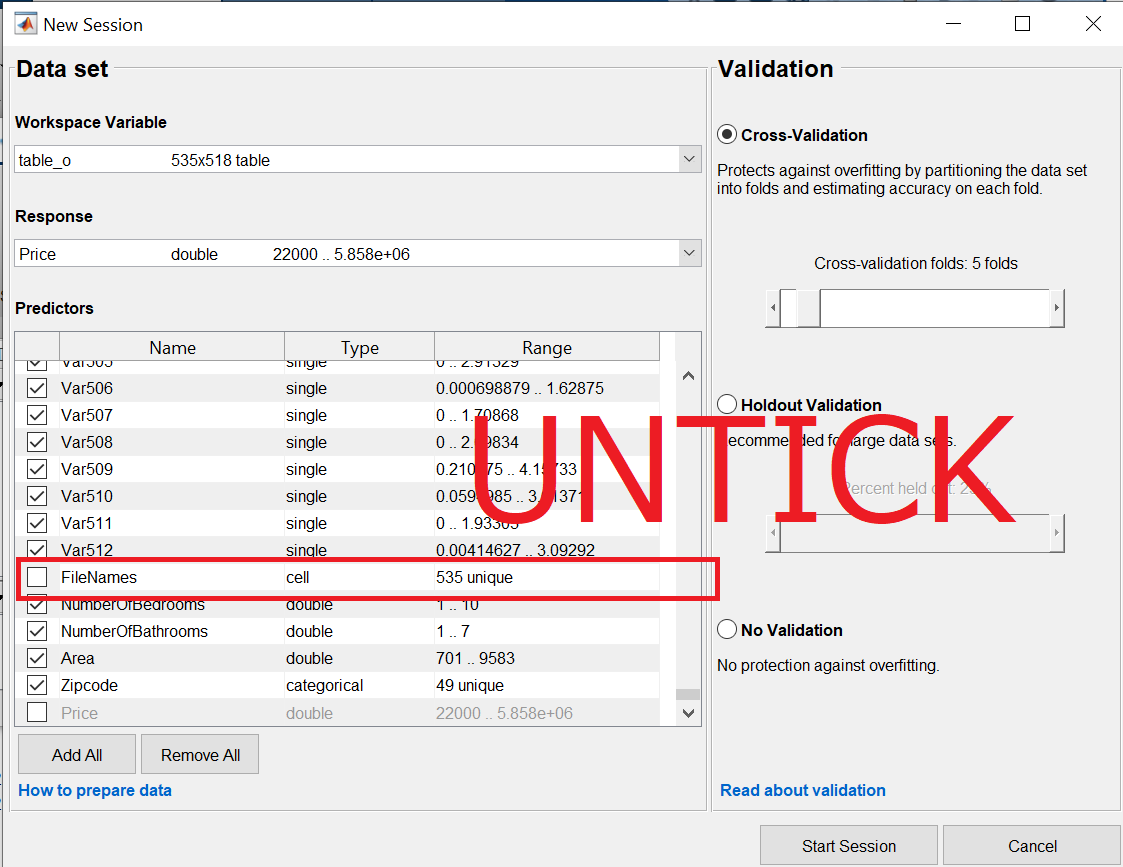

After training, you may export the best model. I have trained the model, you may load the model and justify the accuracy. 

I have save the model in classificationmachinelearning.mat

load regressiondeeplearningmachinelearning.mat
regressiondeeplearningmachinelearning

regressiondeeplearningmachinelearning = struct with fields:
            predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
     RequiredVariables: {1×516 cell}
    RegressionEnsemble: [1×1 classreg.learning.regr.RegressionEnsemble]
                 About: 'This struct is a trained model exported from Regression Learner R2019a.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'

## Justify the accuracy with testing dataset

YPred = regressiondeeplearningmachinelearning.predictFcn(Testing_Data_2);
table_MAE = table(Testing_Data_2.Price,YPred);
table_MAE = rmmissing(table_MAE);
table_MAE.Properties.VariableNames(1)="Price";
table_MAE.Properties.VariableNames(2)="YPred";
MAE = abs(sum(table_MAE.Price-table_MAE.YPred)/numel(table_MAE.Price))

MAE = 1.7694e+04

Price = cur2str(Testing_Data_2.Price,2);
YPred = cur2str(YPred,2);
result=table(Testing_Data_2.FileNames,Price,YPred);
result.Properties.VariableNames(1)="Name";
result.Properties.VariableNames(2)="Actual_Price";
result.Properties.VariableNames(3)="Predicted_Price"

result = 160×3 table
                                                                       Name                                                                        Actual_Price    Predicted_Price
    ___________________________________________________________________________________________________________________________________________    ____________    _______________
    'C:\Users\KevinChng\Desktop\TechSource\Customer Visit\87 Krungsi Bank\1. Reply Email Material\Predict House Price\NewImage\Dataset   2.png'    [1x11 char]       [1x11 char]  
    'C:\Users\KevinChng\Desktop\TechSource\Customer Visit\87 Krungsi Bank\1. Reply Email Material\Predict House Price\NewImage\Dataset   5.png'    [1x11 char]       [1x11 char]  
    'C:\Users\KevinChng\Desktop\TechSource\Customer Visit\87 Krungsi Bank\1. Reply Email Material\Predict House Price\NewImage\Dataset   6.png'    [1x11 char]   

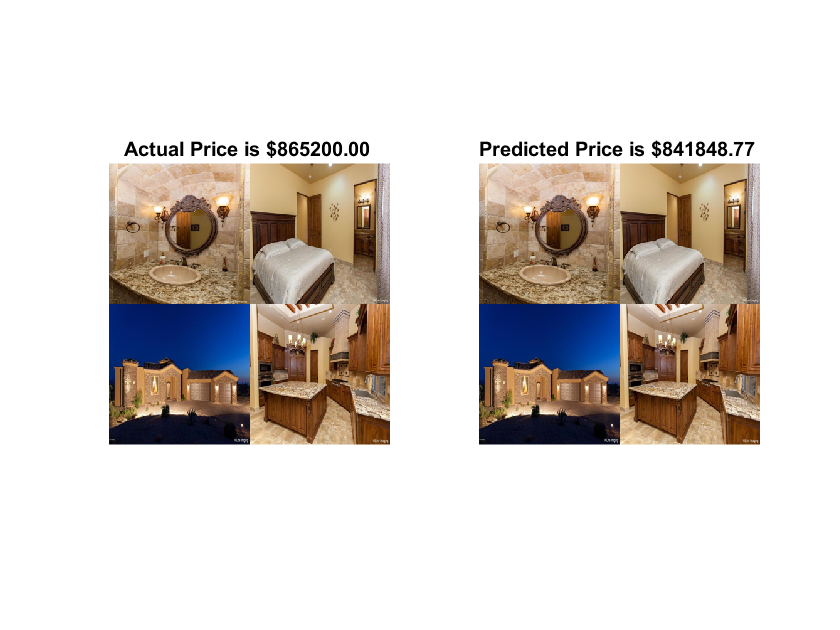

subplot(1,2,1)
imshow(result.Name{1})
title(sprintf("Actual Price is %s",result.Actual_Price(1,:)))
subplot(1,2,2)
imshow(result.Name{1})
title(sprintf("Predicted Price is %s",result.Predicted_Price(1,:)))

## Compare the accuracy of 3 Approaches

%Machine Learning
YPred = regressionmachinelearning.predictFcn(Testing_Data_1);
table_MAE = table(Testing_Data_1.Price,YPred);
table_MAE = rmmissing(table_MAE);
table_MAE.Properties.VariableNames(1)="Price";
table_MAE.Properties.VariableNames(2)="YPred";
MAE(1) = abs(sum(table_MAE.Price-table_MAE.YPred)/numel(table_MAE.Price));

clearvars YPred table_MAE
%Deep Learning
YPred= predict(netTransfer,imdsValidation_nn);
table_MAE = table(imdsValidation.Labels,YPred);
table_MAE = rmmissing(table_MAE);
table_MAE.Properties.VariableNames(1)="Price";
table_MAE.Properties.VariableNames(2)="YPred";
MAE(2) = abs(sum(table_MAE.Price-table_MAE.YPred)/numel(table_MAE.Price));

clearvars YPred table_MAE
%Deep Learning + Machine Learning
YPred = regressiondeeplearningmachinelearning.predictFcn(Testing_Data_2);
table_MAE = table(Testing_Data_2.Price,YPred);
table_MAE = rmmissing(table_MAE);
table_MAE.Properties.VariableNames(1)="Price";
table_MAE.Properties.VariableNames(2)="YPred";
MAE(3) = abs(sum(table_MAE.Price-table_MAE.YPred)/numel(table_MAE.Price));

% Compare 3 approaches in table
compare_table=table(MAE(1),MAE(2),MAE(3));
compare_table.Properties.VariableNames(1)="Machine_Learning";
compare_table.Properties.VariableNames(2)="Deep_Learning";
compare_table.Properties.VariableNames(3)="Deep_Learning_Machine_Learning"

compare_table = 1×3 table
    Machine_Learning    Deep_Learning    Deep_Learning_Machine_Learning
    ________________    _____________    ______________________________
         72490           1.4128e+05                  17694             

It is interesting, seem like the combination technique of Deep Learning and Machine Learning is the best here according to Mean Square Error (MSE).

## Supporting Function

%Resize the Image in the datastore

function data = customReadDatstoreImage(filename)
% code from default function: 
onState = warning('off', 'backtrace'); 
c = onCleanup(@() warning(onState)); 
data = imread(filename); % added lines: 
data = data(:,:,min(1:3, end)); 
data = imresize(data,[224 224]);
end

% Preprocessing the data (Assign classification label to data only purpose to extract feature)

function Data = preprocessing()
Data = importfile("Houses-dataset-master\Houses Dataset\HousesInfo.txt");
for i=1:1:height(Data)
ImageName(i)=sprintf("Dataset%4i.png",i);
end
%Add ImageName to the Data, so it can represent the data
Data.ImageName = ImageName';

%Change the datatype
Data.Price=double(Data.Price);
Data.Zipcode = categorical(Data.Zipcode);

%Now sort the table with price (lowest to highest)
Data = sortrows(Data,"Price");

%Then label it equally with "Very Cheap" "Cheap" "Normal" "Expensive" "Very
%Expensive"
NumberOfImage = height(Data);
Label(1:NumberOfImage/5) = "Very Cheap";
Label(NumberOfImage/5+1:NumberOfImage/5*2) = "Cheap";
Label(NumberOfImage/5*2+1:NumberOfImage/5*3) = "Normal";
Label(NumberOfImage/5*3+1:NumberOfImage/5*4) = "Expensive";
Label(NumberOfImage/5*4+1:NumberOfImage/5*5) = "Super Expensive";

%Add the label to Table
Data.Label = categorical(Label');

%Sort the table by Image_Name
Data = sortrows(Data,"ImageName");

end